x = [
    1.0, 1.0;
    1.5, 2.0;
    3.0, 4.0;
    5.5, 7.0;
    3.5, 5.0;
    4.5, 5.0;
    3.5, 4.5]

x =     1.0000    1.0000
    1.5000    2.0000
    3.0000    4.0000
    5.5000    7.0000
    3.5000    5.0000
    4.5000    5.0000
    3.5000    4.5000


grid
plot(x(:, 1), x(:, 2), 'b.')
% Matriz de clusters, lleva por filas coordenadas de los clusters que hemos
% elegido aleatoriamente entre los puntos dato (se podrían haber tomado 
% como centroides puntos distintos a los de los datos)
cluster_est = [
    x(1, :);
    x(4, :)
    ]

cluster_est =     1.0000    1.0000
    5.5000    7.0000


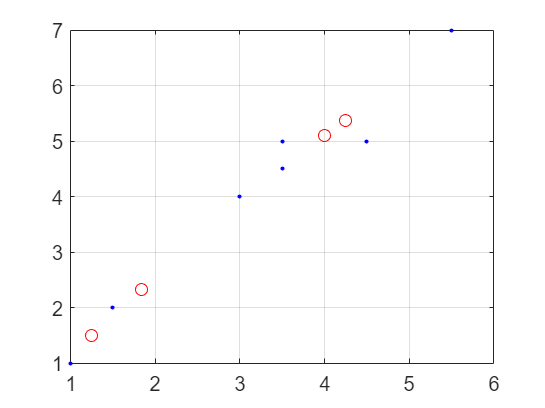

cluster =     1.2500    1.5000
    4.0000    5.1000


i = 3

tol = 0.1;
cluster = kmedias_nojer(x, cluster_est, tol)

% Finalmente para detener el algoritmo calculamos la distancia media
    % entre las coordenadas de los clústers de una iteración y la anterior
    dist = pdist2(cluster_est, cluster);
    dist = diag(dist);
    dist_media = mean(dist);